% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=x on [0;1]
%      2-x on [1;2]
% T=4;

clear
pi1=pi;
syms x real;
syms pi;
f(x)=piecewise(-2<=x<=-1,2+x,-1<=x<=0,-x,0<=x<=1,x,1<=x<=2,2-x)

$$f(x) = \left\{ \begin{array}{cl} x+2 & \text{ if }x\in \left[-2,-1\right]\\ -x & \text{ if }x\in \left[-1,0\right]\\ x & \text{ if }x\in \left[0,1\right]\\ 2-x & \text{ if }x\in \left[1,2\right] \end{array}\right.$$

L=2;

syms m integer;
[a0,a(m),b(m),abf(m)]=fourierseriesL(f,L)

$$a0 = 1$$

$$a(m) = -\frac{4\,{\left(-1\right)}^{m}-8\,\cos\left(\frac{\pi \,m}{2}\right)+4}{m^{2}\,\pi^{2}}$$

$$b(m) = 0$$

$$abf(m) = -\frac{\cos\left(\frac{\pi \,m\,x}{2}\right)\,\left(4\,{\left(-1\right)}^{m}-8\,\cos\left(\frac{\pi \,m}{2}\right)+4\right)}{m^{2}\,\pi^{2}}$$

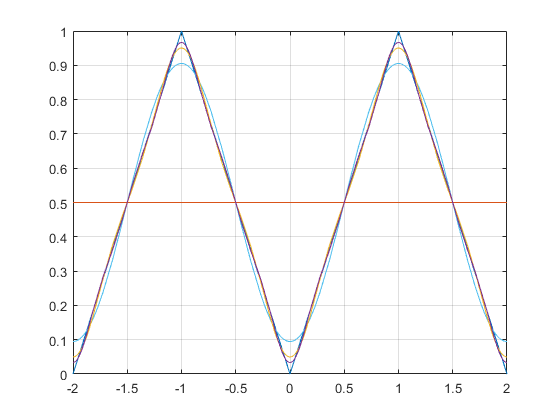


fplot(f(x),[-2 2]);
grid on
hold on

f1=a0/2;
for m=1:10
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-2 2])
    grid on
end
hold off


a0/2

$$ans = \frac{1}{2}$$

% 1/2
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 2 & -\frac{4}{\pi^{2}} & 0 & -\frac{4\,\cos\left(\pi \,x\right)}{\pi^{2}}\\ 3 & 0 & 0 & 0\\ 4 & 0 & 0 & 0\\ 5 & 0 & 0 & 0\\ 6 & -\frac{4}{9\,\pi^{2}} & 0 & -\frac{4\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}}\\ 7 & 0 & 0 & 0\\ 8 & 0 & 0 & 0\\ 9 & 0 & 0 & 0\\ 10 & -\frac{4}{25\,\pi^{2}} & 0 & -\frac{4\,\cos\left(5\,\pi \,x\right)}{25\,\pi^{2}} \end{array}\right)$$

% [  1,            0, 0,                          0]
% [  2,      -4/pi^2, 0,        -(4*cos(pi*x))/pi^2]
% [  3,            0, 0,                          0]
% [  4,            0, 0,                          0]
% [  5,            0, 0,                          0]
% [  6,  -4/(9*pi^2), 0,  -(4*cos(3*pi*x))/(9*pi^2)]
% [  7,            0, 0,                          0]
% [  8,            0, 0,                          0]
% [  9,            0, 0,                          0]
% [ 10, -4/(25*pi^2), 0, -(4*cos(5*pi*x))/(25*pi^2)]


function [a0,a,b,abf]=fourierseriesL(f,L)
syms x real
syms m integer

a0=(1/L)*int(f(x),x,-L,L);
a(m)=(1/L)*int(f*cos(m*pi*x/L),x,-L,L);
a(m)=simplify(subs(a(m),[sin(pi*m),sin((pi*m)/2)^2,cos(pi*m)],...
    [0,(1-(-1)^m)/2,(-1)^m]));
af(m)=a(m)*cos(m*pi*x/L);

b(m)=(1/L)*int(f*sin(m*pi*x/L),x,-L,L);
b(m)=simplify(subs(b(m),[sin(pi*m),sin((pi*m)/2)^2,cos(pi*m)],...
    [0,(1-(-1)^m)/2,(-1)^m]));
bf(m)=b(m)*sin(m*pi*x/L);
abf(m)=af(m)+bf(m);
end